% a)
format long

Dot indexing is not supported for variables of this type.

Error in snapnow (line 119)
                iCell(iCell < 0) = data.lastGo;

Error in LiveEditorEvaluationHelperE1503844744 (line 2)
format long

Error in matlab.internal.editor.evaluateRegions

Error in matlab.internal.editor.EvaluationOutputsService.evalRegions


n = 100;
a = ones(n,1);
Asparse = spdiags([a -4*a 6*a -4*a a], -2:2, n, n);
Asparse(1,1) = 9;
Asparse(n,n) = 1;
Asparse(n,n-1) = -2;
Asparse(n-1,n) = -2;
Asparse(n-1,n-1) = 5;
L = 10;
F = .005;
h = L/n;
b = zeros(n,1);
for i = 1:n
    b(i) = F*h^4;
end
% I)
tic
A1 = Asparse\b;
toc

Elapsed time is 0.007930 seconds.


n1 = norm(A1);
Err1 = condest(Asparse)*(norm(b-Asparse*A1)/norm(b));
% II)
Adense = full(Asparse);
tic
A2 = Adense\b;
toc

Elapsed time is 0.004519 seconds.


n2 = norm(A2);
Err2 = condest(Asparse)*(norm(b-Asparse*A2)/norm(b));
% III)
z = ones(n,1);
tic
[A3, iter, T] = gs2(Asparse, b, z, 1e-8, 1e5)

A3 =    0.000802091443204
   0.004643950421439
   0.011357512661802
   0.020775327689180
   0.032730674660401
   0.047057710727598
   0.063591648472836
   0.082168958977343
   0.102627597118418
   0.124807245726086


iter =       100000


T =    (1,2)      0.444444444444444
   (2,2)      0.296296296296296
   (3,2)      0.123456790123457
   (4,2)      0.032921810699588
   (5,2)      0.001371742112483
   (6,2)     -0.004572473708276
   (7,2)     -0.003276939490931
   (8,2)     -0.001422547375908
   (9,2)     -0.000402208335450
  (10,2)     -0.000031047660982
  (11,2)      0.000046336281920
  (12,2)      0.000036065464777
  (13,2)      0.000016320929531
  (14,2)      0.000004869708891
  (15,2)      0.000000526317672
  (16,2)     -0.000000460739700
  (17,2)     -0.000000394879412
  (18,2)     -0.000000186462991
  (19,2)     -0.000000058495426
  (20,2)     -0.000000007919785
  (21,2)      0.000000004469381
  (22,2)      0.000000004299551
  (23,2)      0.000000002121471
  (24,2)      0.000000000697722
  (25,2)      0.000000000111570
  (26,2)     -0.000000000041907
  (27,2)     -0.000000000046533
  (28,2)     -0.000000000024038
  (29,2)     -0.000000000008270
  (30,2)     -0.000000000001507
  (31,2)      0.000000000000374
  (3

toc

Elapsed time is 0.522674 seconds.


n3 = norm(A3);
% b)
U = spdiags([a, -2*a a], 0:2, n, n);
U(1,1) = 2;
full(U);
tic
z = U\b;
x1 = U'\z;
toc

Elapsed time is 0.008073 seconds.


n4 = norm(x1);
% c)
CAsparse = condest(Asparse);
CU = condest(U);
p = max(abs(eig(full(T))));
% d)
x = 0;
for j = 1:n
    x(j) = j*h;
end
    EI = (F*L^4)./(6*max(x1))

EI =    1.328902771493179


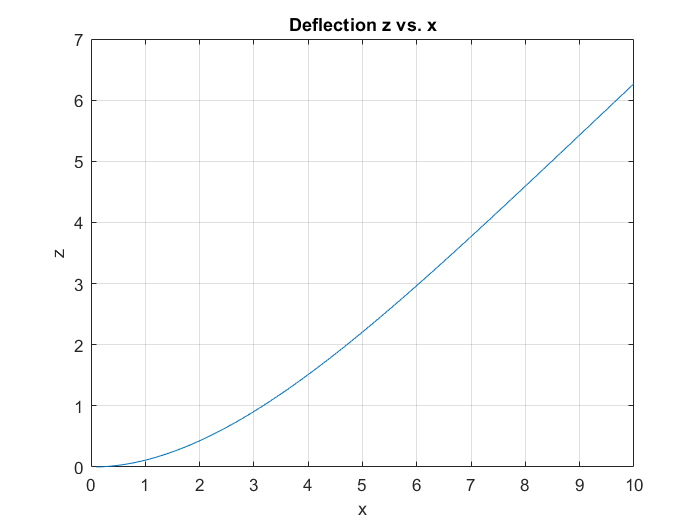

plot(x, x1)
grid on
title("Deflection z vs. x")
xlabel("x")
ylabel("z")